clear;clc;
%load data set
load("SP1bs_F_lower.mat");
load("SP1bs_F_mean.mat");
load("SP1bs_F_upper.mat");
load("SP1bs_M_lower.mat");
load("SP1bs_M_mean.mat");
load("SP1bs_M_upper.mat");

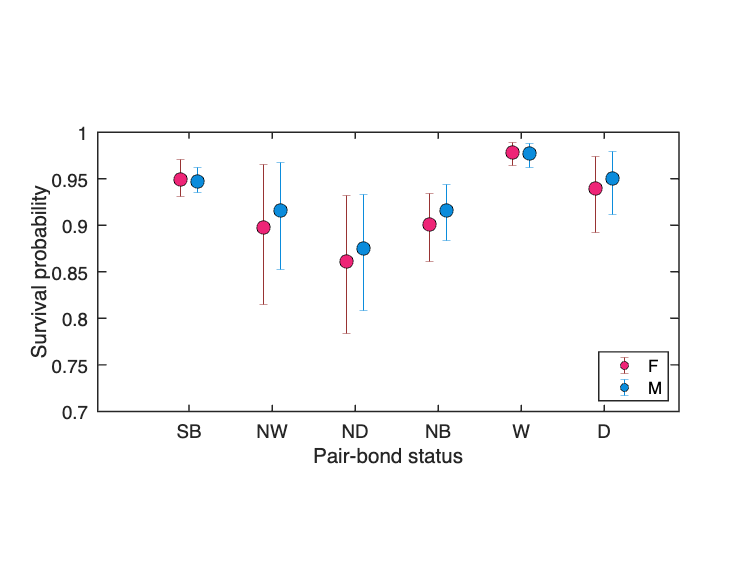

%survival
fig=figure;
f_x = 1:1:6; hold on
m_x = f_x+0.2;
f_y = [F_mean.s_SB,F_mean.s_NW,F_mean.s_ND,F_mean.s_NB,F_mean.s_W,F_mean.s_D];
f_yneg = [F_lower.s_SB,F_lower.s_NW,F_lower.s_ND,F_lower.s_NB,F_lower.s_W,F_lower.s_D]-f_y;
f_ypos = [F_upper.s_SB,F_upper.s_NW,F_upper.s_ND,F_upper.s_NB,F_upper.s_W,F_upper.s_D]-f_y;
m_y = [M_mean.s_SB,M_mean.s_NW,M_mean.s_ND,M_mean.s_NB,M_mean.s_W,M_mean.s_D];
m_yneg = [M_lower.s_SB,M_lower.s_NW,M_lower.s_ND,M_lower.s_NB,M_lower.s_W,M_lower.s_D]-m_y;
m_ypos = [M_upper.s_SB,M_upper.s_NW,M_upper.s_ND,M_upper.s_NB,M_upper.s_W,M_upper.s_D]-m_y;
errorbar(f_x,f_y,f_yneg,f_ypos,'o','Color',[153 51 51]/256,'MarkerEdgeColor','k','MarkerFaceColor',[239 37 119]/256,"Markersize",10);
errorbar(m_x,m_y,m_yneg,m_ypos,'o','Color',[11 141 221]/256,'MarkerEdgeColor','k','MarkerFaceColor',[11 141 221]/256,"Markersize",10);
xlim([0 7])
ylim([0.7 1])
xticks(f_x+0.1)
xticklabels({'SB', 'NW', 'ND','NB',"W","D"})
pbaspect([2.5 1.2 1]);
box on
legend('F','M','Location',"southeast");
set(gca, 'FontName', 'Helvetica')
ylabel('Survival probability');xlabel('Pair-bond status');
set(gca,'linewidth',1.1,'fontsize',14,'fontname','Helvetica')
%print(gcf,'survival.pdf','-dpdf','-r600'); 
exportgraphics(fig,'survival.pdf','BackgroundColor','none')
exportgraphics(fig,'survival.png','BackgroundColor','white')

%widowhood
fig=figure;
fig.Position=[560,240,350,400]

fig =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [560 240 350 400]
       Units: 'pixels'

  Show all properties


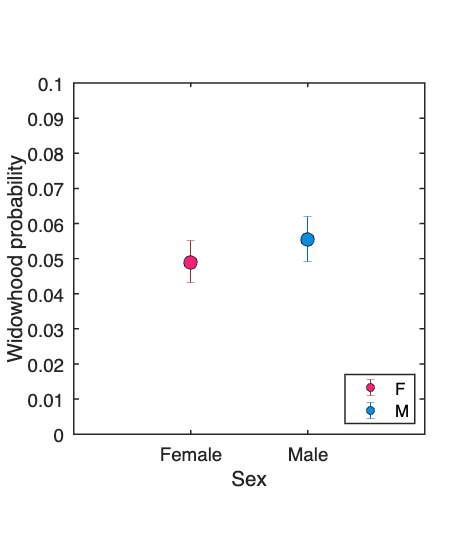

f_x = 1; hold on 
m_x = 2;
f_y =F_mean.w_SB;
f_yneg =F_lower.w_SB -f_y;
f_ypos =F_upper.w_SB -f_y;
m_y =M_mean.w_SB;
m_yneg =M_lower.w_SB -m_y;
m_ypos =M_upper.w_SB -m_y;
errorbar(f_x,f_y,f_yneg,f_ypos,'o','Color',[153 51 51]/256,'MarkerEdgeColor','k','MarkerFaceColor',[239 37 119]/256,"Markersize",10);
errorbar(m_x,m_y,m_yneg,m_ypos,'o','Color',[0 102 204]/256,'MarkerEdgeColor','k','MarkerFaceColor',[11 141 221]/256,"Markersize",10);
xlim([0 3])
ylim([0 0.1])
xticks([f_x m_x])
xticklabels({'Female', 'Male'})
set(gca,'linewidth',1.1,'fontsize',14,'fontname','Helvetica')
pbaspect([1.2 1.2 1]);
box on
set(gca,'linewidth',1.1,'fontsize',14,'fontname','Helvetica')
ylabel('Widowhood probability'); xlabel("Sex")
legend('F','M','Location',"southeast");
%print(gcf,'widowhood.pdf','-dpdf','-r600'); 
exportgraphics(fig,'widowhood.pdf','BackgroundColor','none')
exportgraphics(fig,'widowhood.png','BackgroundColor','none')

%divorce
fig=figure

fig =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [455 334 560 420]
       Units: 'pixels'

  Show all properties


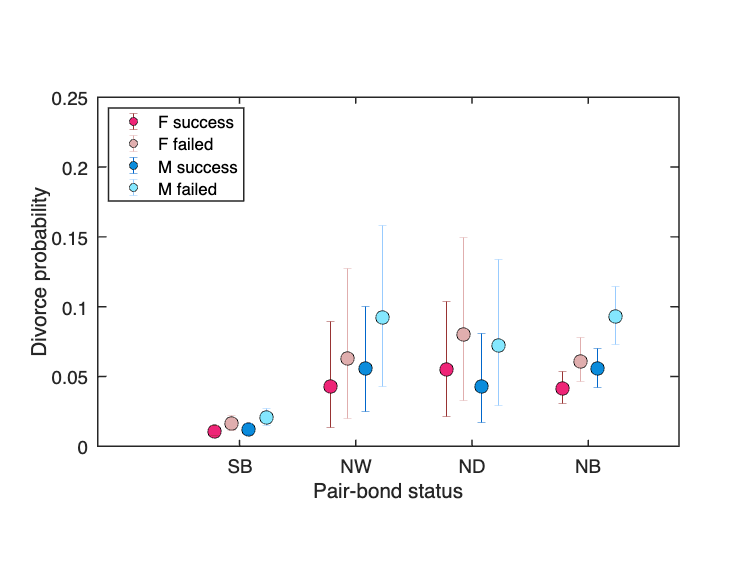

f_x = 1:1:4; hold on
failed_f_x = f_x+0.15;
m_x = f_x+0.3; 
failed_m_x = f_x+0.45;
f_y = [F_mean.d_SB,F_mean.d_NW,F_mean.d_ND,F_mean.d_NB];
f_yneg = [F_lower.d_SB,F_lower.d_NW,F_lower.d_ND,F_lower.d_NB]-f_y;
f_ypos = [F_upper.d_SB,F_upper.d_NW,F_upper.d_ND,F_upper.d_NB]-f_y;
%individuals failed at their previous breeding attempts
failed_f_y = [F_mean.d_SBf,F_mean.d_NWf,F_mean.d_NDf,F_mean.d_NBf];
failed_f_yneg = [F_lower.d_SBf,F_lower.d_NWf,F_lower.d_NDf,F_lower.d_NBf]-failed_f_y;
failed_f_ypos = [F_upper.d_SBf,F_upper.d_NWf,F_upper.d_NDf,F_upper.d_NBf]-failed_f_y;
m_y = [M_mean.d_SB,M_mean.d_NW,M_mean.d_ND,M_mean.d_NB];
m_yneg = [M_lower.d_SB,M_lower.d_NW,M_lower.d_ND,M_lower.d_NB]-m_y;
m_ypos = [M_upper.d_SB,M_upper.d_NW,M_upper.d_ND,M_upper.d_NB]-m_y;
%individuals failed at their previous breeding attempts
failed_m_y = [M_mean.d_SBf,M_mean.d_NWf,M_mean.d_NDf,M_mean.d_NBf];
failed_m_yneg = [M_lower.d_SBf,M_lower.d_NWf,M_lower.d_NDf,M_lower.d_NBf]-failed_m_y;
failed_m_ypos = [M_upper.d_SBf,M_upper.d_NWf,M_upper.d_NDf,M_upper.d_NBf]-failed_m_y;

errorbar(f_x,f_y,f_yneg,f_ypos,'o','Color',[153 51 51]/256,'MarkerEdgeColor','k','MarkerFaceColor',[239 37 119]/256,"Markersize",10);
errorbar(failed_f_x,failed_f_y,failed_f_yneg,failed_f_ypos,'o','Color',[225 175 175]/256,'MarkerEdgeColor','k','MarkerFaceColor',[225 175 175]/256,"Markersize",10);
errorbar(m_x,m_y,m_yneg,m_ypos,'o','Color',[0 102 204]/256,'MarkerEdgeColor','k','MarkerFaceColor',[11 141 221]/256,"Markersize",10);
errorbar(failed_m_x,failed_m_y,failed_m_yneg,failed_m_ypos,'o','Color',[153, 204, 255]/256,'MarkerEdgeColor','k','MarkerFaceColor',[133, 232, 255]/256,"Markersize",10);
xlim([0 5])
ylim([0 0.25])
xticks(f_x+0.22)
xticklabels({'SB', 'NW', 'ND','NB'})
set(gca,'linewidth',1.1,'fontsize',10,'fontname','Helvetica')
pbaspect([2 1.2 1]);
box on
legend('F success',"F failed",'M success',"M failed",'Location',"northwest");
set(gca, 'FontName', 'Helvetica')
ylabel('Divorce probability');xlabel('Pair-bond status');
set(gca,'linewidth',1.1,'fontsize',14,'fontname','Helvetica')
%print(gcf,'divorce.pdf','-dpdf','-r600'); 
exportgraphics(fig,'divorce.pdf','BackgroundColor','none')
exportgraphics(fig,'divorce.png','BackgroundColor','none')

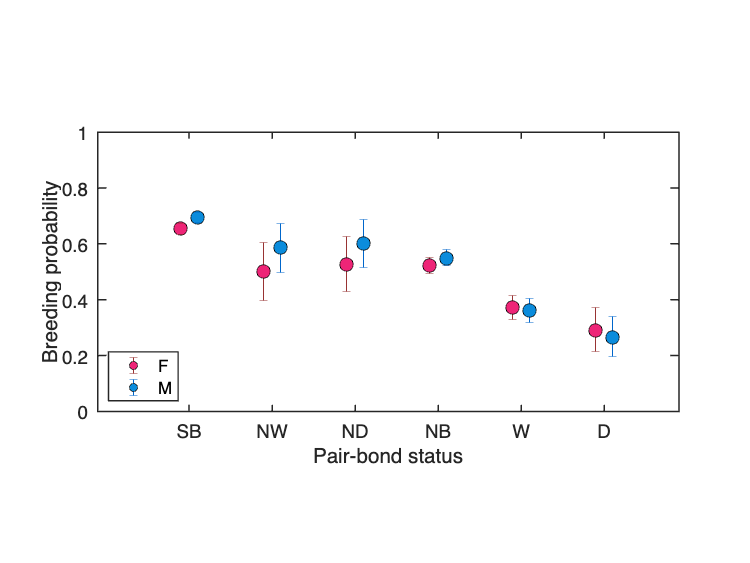

%breeding
fig=figure;
f_x = 1:1:6; hold on
m_x = f_x+0.2;
f_y = [F_mean.beta_SB,F_mean.beta_NW,F_mean.beta_ND,F_mean.beta_NB,F_mean.beta_W,F_mean.beta_D];
f_yneg = [F_lower.beta_SB,F_lower.beta_NW,F_lower.beta_ND,F_lower.beta_NB,F_lower.beta_W,F_lower.beta_D]-f_y;
f_ypos = [F_upper.beta_SB,F_upper.beta_NW,F_upper.beta_ND,F_upper.beta_NB,F_upper.beta_W,F_upper.beta_D]-f_y;
%m_y = [0.695,0.690,0.650,0.509,0.337,0.365];
%m_yneg = [0.678,0.543,0.602,0.484,0.237,0.292]-m_y;
%m_ypos = [0.711,0.819,0.697,0.533,0.441,0.437]-m_y;
m_y = [M_mean.beta_SB,M_mean.beta_NW,M_mean.beta_ND,M_mean.beta_NB,M_mean.beta_W,M_mean.beta_D];
m_yneg = [M_lower.beta_SB,M_lower.beta_NW,M_lower.beta_ND,M_lower.beta_NB,M_lower.beta_W,M_lower.beta_D]-m_y;
m_ypos = [M_upper.beta_SB,M_upper.beta_NW,M_upper.beta_ND,M_upper.beta_NB,M_upper.beta_W,M_upper.beta_D]-m_y;
errorbar(f_x,f_y,f_yneg,f_ypos,'o','Color',[153 51 51]/256,'MarkerEdgeColor','k','MarkerFaceColor',[239 37 119]/256,"Markersize",10);
errorbar(m_x,m_y,m_yneg,m_ypos,'o','Color',[0 102 204]/256,'MarkerEdgeColor','k','MarkerFaceColor',[11 141 221]/256,"Markersize",10);
xlim([0 7])
ylim([0 1])
xticks(f_x+0.1)
xticklabels({'SB', 'NW', 'ND','NB',"W","D"})
set(gca,'linewidth',1.1,'fontsize',14,'fontname','Helvetica')
pbaspect([2.5 1.2 1]);
box on
legend('F','M','Location',"southwest");
set(gca, 'FontName', 'Helvetica')
ylabel('Breeding probability');xlabel('Pair-bond status');
%print(gcf,'breeding.pdf','-dpdf','-r600'); 
exportgraphics(fig,'breeding.pdf','BackgroundColor','none')
exportgraphics(fig,'breeding.png','BackgroundColor','none')

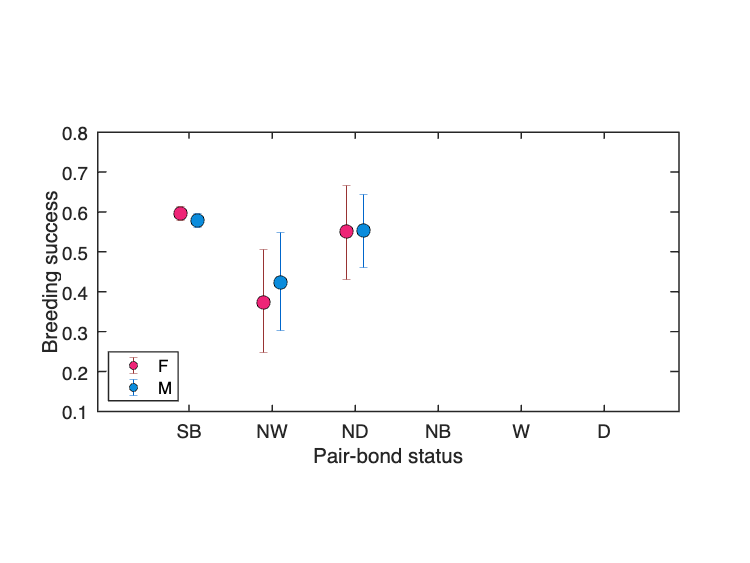

%breeding
fig=figure;
f_x = 1:1:6; hold on
m_x = f_x+0.2;
f_y = [F_mean.f_SB,F_mean.f_NW,F_mean.f_ND];
f_yneg = [F_lower.f_SB,F_lower.f_NW,F_lower.f_ND]-f_y;
f_ypos = [F_upper.f_SB,F_upper.f_NW,F_upper.f_ND]-f_y;
m_y = [M_mean.f_SB,M_mean.f_NW,M_mean.f_ND];
m_yneg = [M_lower.f_SB,M_lower.f_NW,M_lower.f_ND]-m_y;
m_ypos = [M_upper.f_SB,M_upper.f_NW,M_upper.f_ND]-m_y;
errorbar(f_x(1:3),f_y(1:3),f_yneg,f_ypos,'o','Color',[153 51 51]/256,'MarkerEdgeColor','k','MarkerFaceColor',[239 37 119]/256,"Markersize",10);
errorbar(m_x(1:3),m_y(1:3),m_yneg,m_ypos,'o','Color',[0 102 204]/256,'MarkerEdgeColor','k','MarkerFaceColor',[11 141 221]/256,"Markersize",10);
xlim([0 7])
ylim([0.1 0.8])
xticks(f_x+0.1)
xticklabels({'SB', 'NW', 'ND','NB',"W","D"})
set(gca,'linewidth',1.1,'fontsize',14,'fontname','Helvetica')
pbaspect([2.5 1.2 1]);
box on
legend('F','M','Location',"southwest");
set(gca, 'FontName', 'Helvetica')
ylabel('Breeding success');xlabel('Pair-bond status');
%print(gcf,'breeding.pdf','-dpdf','-r600'); 
exportgraphics(fig,'success_crop.pdf','BackgroundColor','none')
exportgraphics(fig,'success_crop.png','BackgroundColor','none')